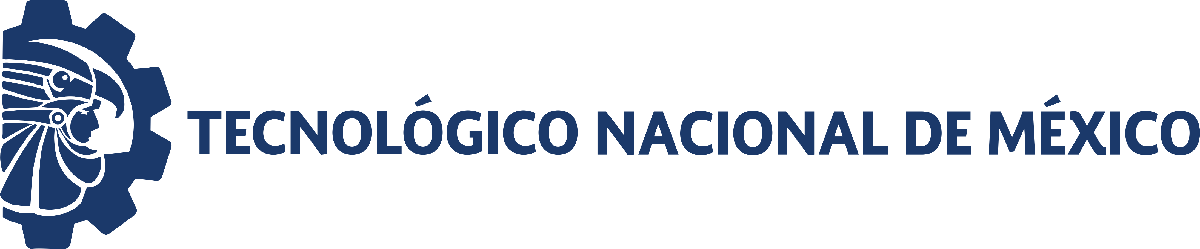                                 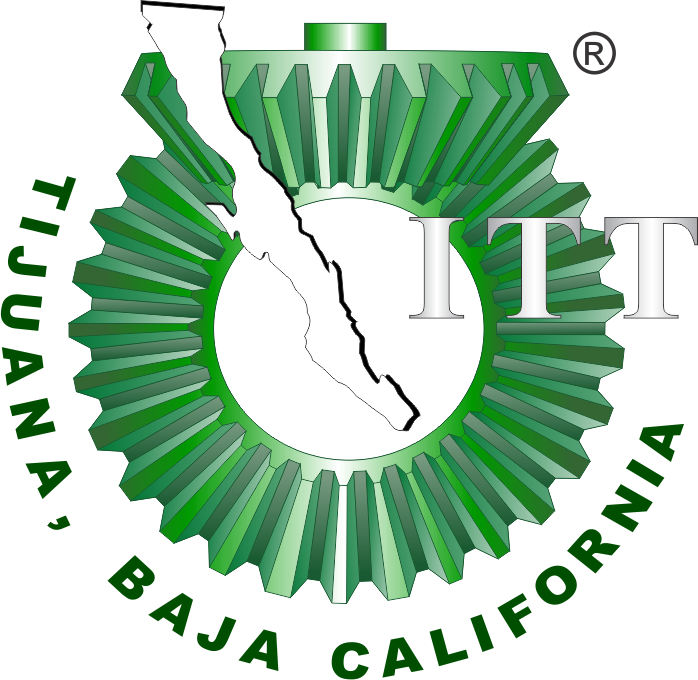

# Práctica 2: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

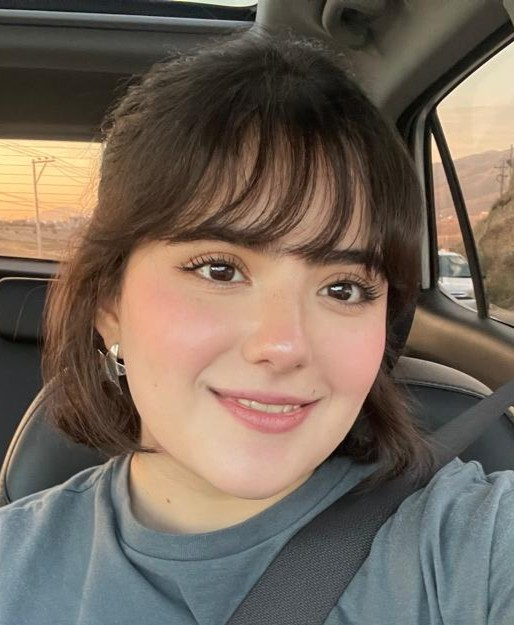

Nombre del alumno: **Nicole Zoe Camacho Quezada**

Número de control: **22211747**

Correo institucional: **L22211747@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema2';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

set_param('Sistema2/Ppa(t)', 'Minimum', '-0.2');
set_param('Sistema2/Ppa(t)', 'Maximum', '1');
set_param('Sistema2/Ppa(t)', 'Seed', '106');
set_param('Sistema2/Ppa(t)', 'SampleTime', '0.5');


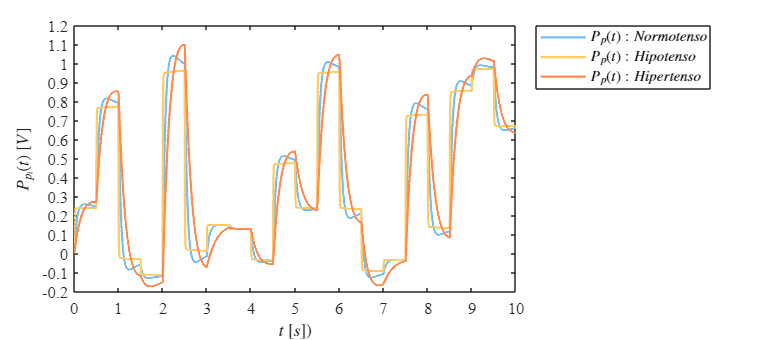

Signal = 'Lazo abierto';
x1 = sim(file, parameters);
writematrix(x1.Ppa, 'signal.xlsx')
plotsignal(x1.t, x1.Pp0, x1.Pp1, x1.Pp2, Signal)

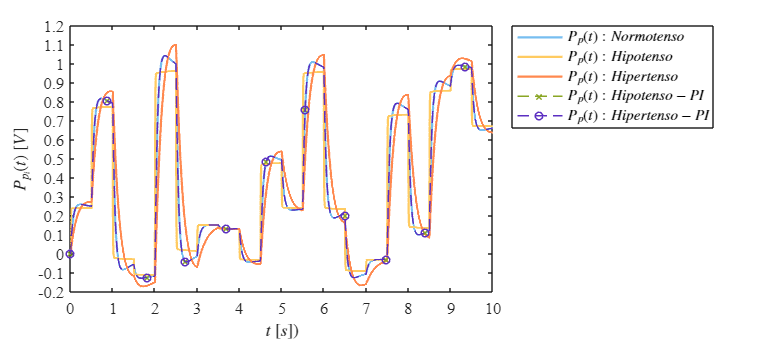

Signal='Lazo cerrado';
x2 = sim(file, parameters);
plotsignals(x2.t, x2.Pp0, x2.Pp1, x2.Pp2, x2.Pp3, x2.Pp4, Signal)

## Función: Respuesta a las senales

function plotsignal(t, Pp0, Pp1, Pp2, Signal)
    set(figure(),'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName', 'Times New Roman', 'FontSize', 11)
    hold on; grid off; box on;
    
    mycolors = [119, 190, 240;
                255, 203, 097;
                255, 137, 079;
                138, 166, 036;
                092, 047, 194; 
                234, 91, 111]/255;
    colororder(mycolors)

    plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-',...
        'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
 
    L = legend('$P_p(t) : Normotenso$', '$P_p(t) : Hipotenso$', '$P_p(t) : Hipertenso$');
    set(L, 'Interpreter', 'Latex','FontSize',10,'Location','BestOutside', 'Box','On');
            
    
    xlabel('$t$ $[s]$)', 'Interpreter', 'Latex ', 'Fontsize', 11)
    ylabel('$P_{p_i}(t)$ $[V]$', 'Interpreter', 'Latex ', 'Fontsize', 11)
    
 
    xlim([0,10]); xticks(0:1:10)
    if Signal=="Lazo abierto"
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)
    end

    exportgraphics(gcf,[Signal,'.pdf'], 'ContentType', 'Vector')
    exportgraphics(gcf,[Signal,'.png'], 'ContentType', 'Vector')
end

function plotsignals(t, Pp0, Pp1, Pp2, Pp3, Pp4, Signal)
    set(figure(),'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName', 'Times New Roman', 'FontSize', 11)
    hold on; grid off; box on;
    
    mycolors = [119, 190, 240;
                255, 203, 097;
                255, 137, 079;
                138, 166, 036;
                092, 047, 194; 
                234, 91, 111]/255;
    colororder(mycolors)

    p = plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-', t, Pp3, '--x', t, Pp4,'--o',...
        'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
        set(p(4), 'LineWidth', 1); set(p(5), 'LineWidth', 1);
    L = legend('$P_p(t) : Normotenso$', '$P_p(t) : Hipotenso$', '$P_p(t) : Hipertenso$', '$P_p(t) : Hipotenso - PI$', '$P_p(t) : Hipertenso - PI$');
    set(L, 'Interpreter', 'Latex','FontSize',10,'Location','BestOutside', 'Box','On');
            
    
    xlabel('$t$ $[s]$)', 'Interpreter', 'Latex ', 'Fontsize', 11)
    ylabel('$P_{p_i}(t)$ $[V]$', 'Interpreter', 'Latex ', 'Fontsize', 11)
    
 
    xlim([0,10]); xticks(0:1:10)
    if Signal=="Lazo cerrado"
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)
    end
    exportgraphics(gcf,[Signal,'.pdf'], 'ContentType', 'Vector')
    exportgraphics(gcf,[Signal,'.png'], 'ContentType', 'Vector')
end

